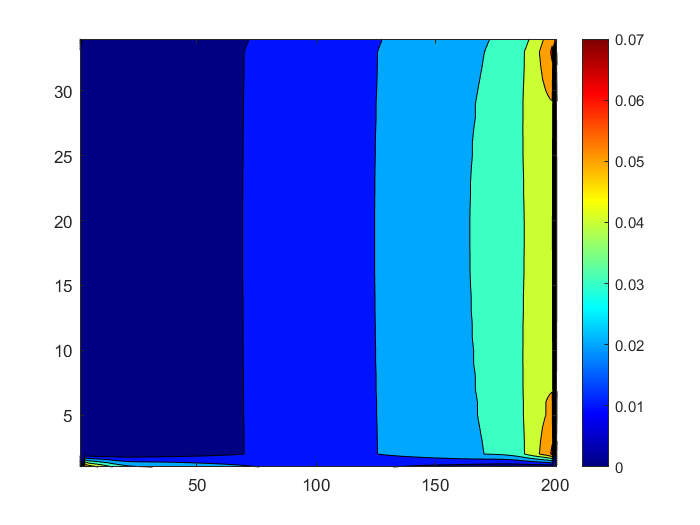

newData = readmatrix("2d_structured_200x20_016ms.csv");
newData = rmmissing(newData);
checker = newData(:,3)>0;
Data2 = newData(checker,:);
x2 = Data2(:,1);
y2= Data2(:,2);
p2 = Data2(:,4);
u2 = Data2(:,5);
v2 = Data2(:,7);
[~,i2y,~] = unique(round(y2,4));
[~,i2x,~] = unique(round(x2,4));
Pmap = NaN(size(i2x,1),size(i2y,1),5);
for n = 1:34
        g = round(y2,4) == round(y2((i2y(n))),4);
        if sum(g)<201
            g = round(y2,3) == round(y2((i2y(n))),3);
            if sum(g)<201
                g = round(y2,2) == round(y2((i2y(n))),2);
            end
        end
        Pmap(1:sum(g),n,1) = p2(g);
        Pmap(1:sum(g),n,2) = u2(g);
        Pmap(1:sum(g),n,3) = v2(g);
        Pmap(1:sum(g),n,4) = x2(g);
        Pmap(1:sum(g),n,5) = y2(g);
end
Pmap;
contourf(Pmap(:,:,1)')
colormap jet
colorbar

% contourf(Pmap(:,:,2)')
% colormap jet
% colorbar
% contourf(Pmap(:,:,3)')
% colormap jet
% colorbar
% contourf(Pmap(:,:,4)')
% colormap jet
% colorbar
% contourf(Pmap(:,:,5)')
% colormap jet
% colorbar
save('PmapZpos.mat','Pmap');
clear

newData = readmatrix("2d_structured_200x20_016ms.csv");
newData = rmmissing(newData);
checker = newData(:,3)<0;
Data2 = newData(checker,:);
x2 = Data2(:,1);
y2= Data2(:,2);
p2 = Data2(:,4);
u2 = Data2(:,5);
v2 = Data2(:,7);
[y2r,i2y,yi] = unique(round(y2,4));
[x2r,i2x,xi] = unique(round(x2,4));
Pmap = NaN(size(i2x,1),size(i2y,1),3);
for n = 1:34
        g = round(y2,4) == round(y2((i2y(n))),4);
        if sum(g)<201
            g = round(y2,3) == round(y2((i2y(n))),3);
            if sum(g)<201
                g = round(y2,2) == round(y2((i2y(n))),2);
            end
        end
        Pmap(1:sum(g),n,1) = p2(g);
        Pmap(1:sum(g),n,2) = u2(g);
        Pmap(1:sum(g),n,3) = v2(g);
        Pmap(1:sum(g),n,4) = x2(g);
        Pmap(1:sum(g),n,5) = y2(g);
end
Pmap;
contourf(Pmap(:,:,1)')
colormap jet
colorbar

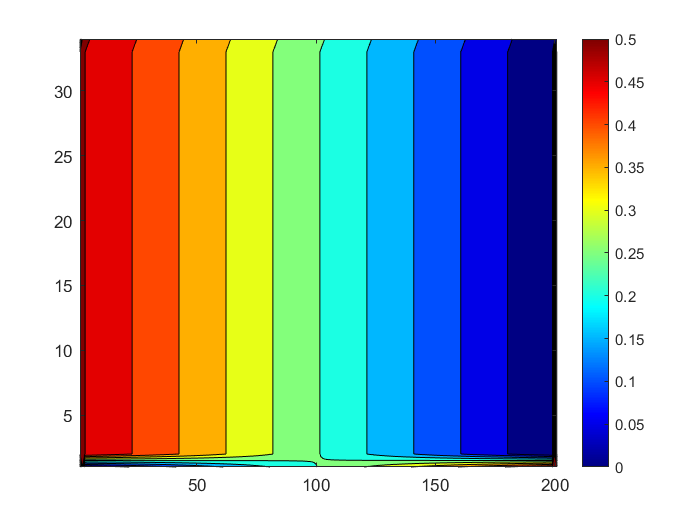

% contourf(Pmap(:,:,2)')
% colormap jet
% colorbar
% contourf(Pmap(:,:,3)')
% colormap jet
% colorbar
% contourf(Pmap(:,:,4)')
% colormap jet
% colorbar

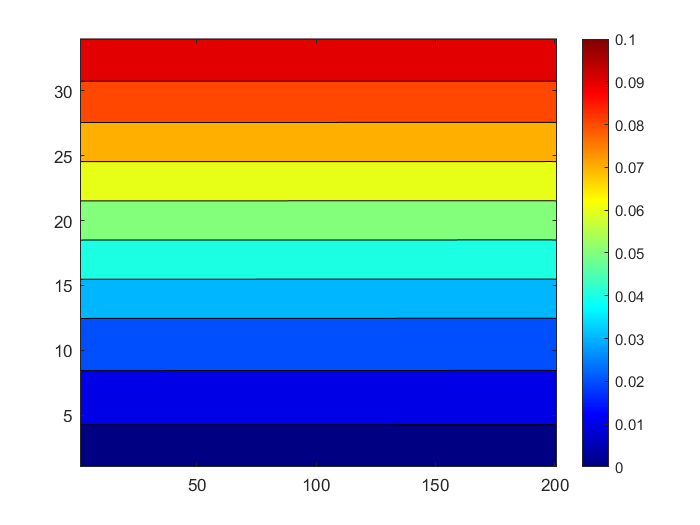

ans =     0.5055    0.5029    0.5004    0.4978    0.4953    0.4928    0.4902    0.4877    0.4851    0.4826    0.4801    0.4775    0.4750    0.4724    0.4699    0.4674    0.4648    0.4623    0.4597    0.4572    0.4547    0.4521    0.4496    0.4470    0.4445    0.4420    0.4394    0.4369    0.4343    0.4318    0.4293    0.4267    0.4242    0.4216    0.4191    0.4166    0.4140    0.4115    0.4089    0.4064    0.4039    0.4013    0.3988    0.3962    0.3937    0.3912    0.3886    0.3861    0.3835    0.3810


% contourf(Pmap(:,:,5)')
% colormap jet
% colorbar

save('PmapZneg.mat','Pmap');
clear